## Identifying a model for a PMSM

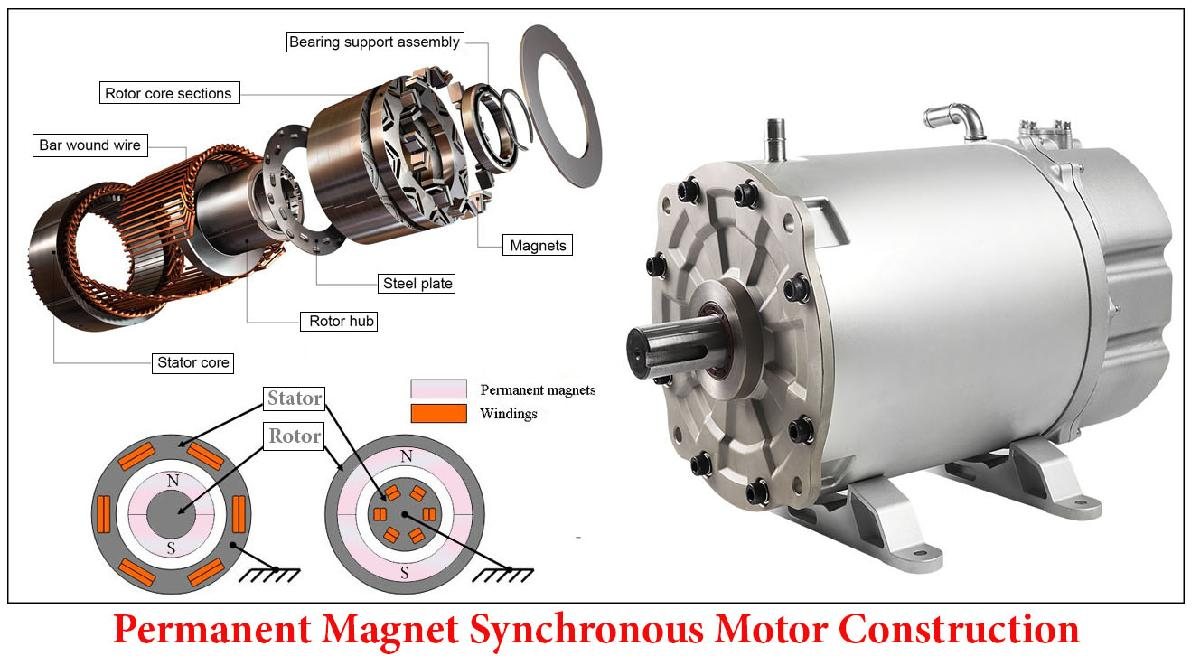

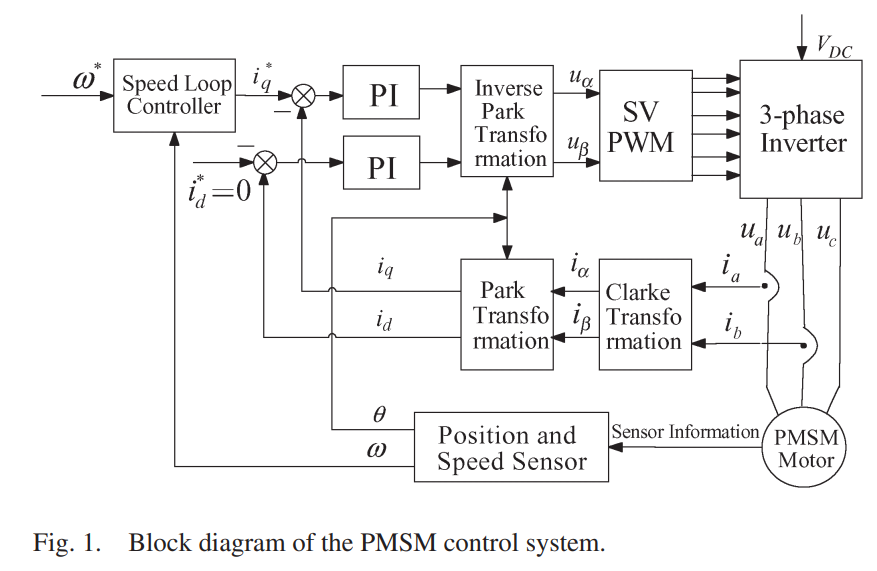

From Liu and Li "Speed control for PMSM Servo system" IEEE tr Ind Elec Vol 59, 2012

The motor is governed by the following system of differential equations

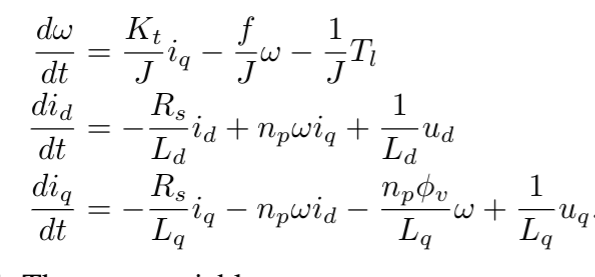

## Generate input data


h = 0.1;
uu = idinput(600, 'prbs', [0, 0.8]);

currentMagnitude = 8;
u1 = currentMagnitude*uu(1:300);
u1v = currentMagnitude*uu(301:600);
t = (0:299)'*h;
input1 = cat(2, t, u1);
input1v = cat(2, t, u1v);


## Load data

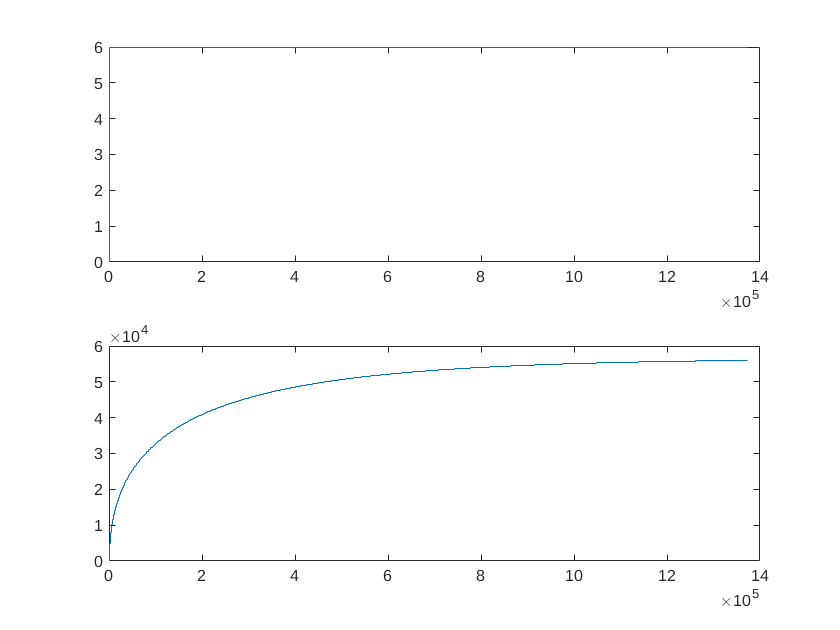

h = 1e-2;

load pmsm_step_sim.mat
ustep = uy.Data(:,1);
ystep = uy.Data(:,2);
figure()
subplot(211);
stairs(ustep)
subplot(212)
stairs(ystep)

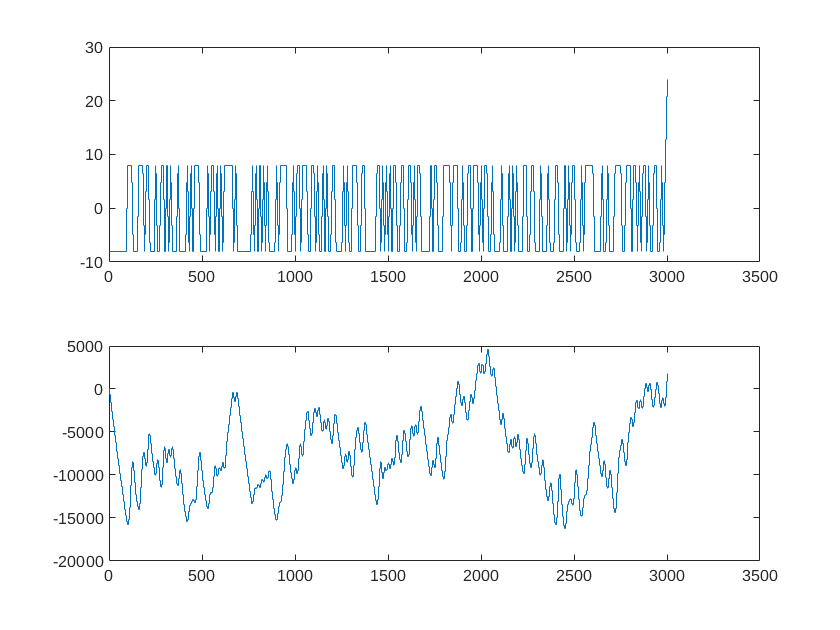


load pmsm_sysid_sim.mat
uident = uy.Data(:,1);
yident = uy.Data(:,2);
figure()
subplot(211);
stairs(uident)
subplot(212)
stairs(yident)

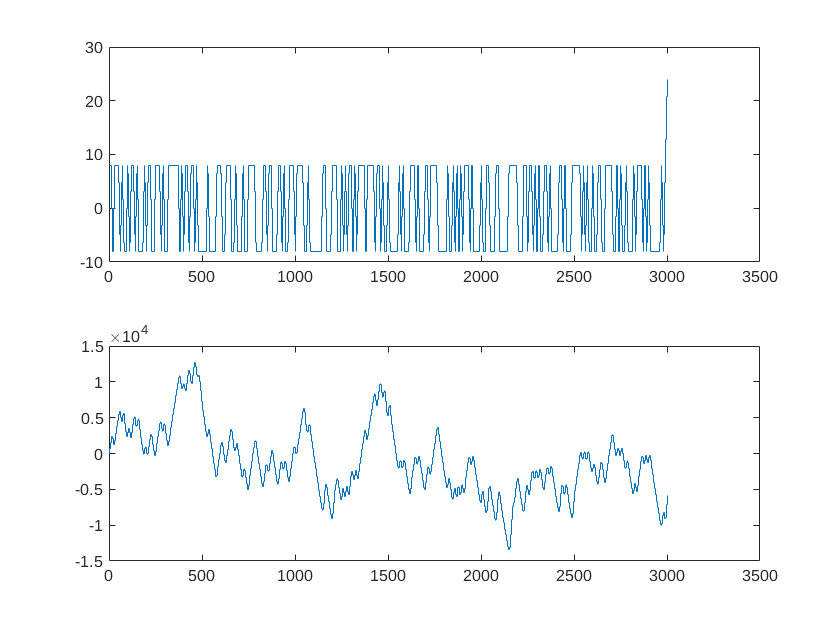


load pmsm_sysid_val_sim.mat
uval = uy.Data(:,1);
yval = uy.Data(:,2);
figure()
subplot(211);
stairs(uval)
subplot(212)
stairs(yval)

## Estimate models

iddta1 = iddata(yident,uident, h);
valdta1 = iddata(yval, uval, h);

% Second order model, one zero, two poles, one delay
% (b0 z + b1) / (z^2 + a1z + a2)
arx221 = arx(iddta1, [2, 2, 1])

arx221 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 1.895 z^-1 + 0.8952 z^-2              
                                                   
  B(z) = 9.841 z^-1 - 6.073 z^-2                   
                                                   
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=2   nk=1
   Number of free coefficients: 4
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 99.5% (prediction focus) 
FPE: 472.7, MSE: 470.9                           



% Second order model, one zero, two poles, two delays
% (b0 z + b1) /(z*(z^2 + a1z + a2))
arx222 = arx(iddta1, [2, 2, 2])

arx222 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 1.925 z^-1 + 0.9253 z^-2              
                                                   
  B(z) = 15.39 z^-2 - 12.68 z^-3                   
                                                   
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=2   nk=2
   Number of free coefficients: 4
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 99.53% (prediction focus)
FPE: 426.6, MSE: 424.9                           



% fourth order model, three zeros, four poles, one delay
% (b0 z^3 + b1z^2 + b2z + b3) / (z^4 + a1z^3 + a2z^2 + a3z + a4)
arx441 = arx(iddta1, [4, 4, 1])

arx441 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)            
  A(z) = 1 - 3.224 z^-1 + 3.834 z^-2 - 1.956 z^-3 + 0.3467 z^-4
                                                               
  B(z) = 2.157 z^-1 + 4.18 z^-2 - 12.44 z^-3 + 7.024 z^-4      
                                                               
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=4   nk=1
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 99.9% (prediction focus) 
FPE: 20.64, MSE: 20.47                           



% sixth order model, five zeros, six poles, one delay
arx661 = arx(iddta1, [6, 6, 1])

arx661 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                        
  A(z) = 1 - 3.379 z^-1 + 4.448 z^-2 - 2.953 z^-3 + 1.183 z^-4 - 0.3692 z^-5 + 0.06983 z^-6
                                                                                           
  B(z) = 2.119 z^-1 + 3.919 z^-2 - 12.83 z^-3 + 9.303 z^-4 - 2.498 z^-5 + 0.861 z^-6       
                                                                                           
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=6   nb=6   nk=1
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 99.9% (prediction focus) 
FPE: 19.31, MSE: 19.08                           



% eigth order model, seven zeros, eight poles, one delay
arx881 = arx(iddta1, [8, 8, 1])

arx881 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                                    
                                                                                                                       
  A(z) = 1 - 3.377 z^-1 + 4.447 z^-2 - 2.966 z^-3 + 1.225 z^-4 - 0.4614 z^-5 + 0.1891 z^-6 - 0.0753 z^-7 + 0.01769 z^-8
                                                                                                                       
  B(z) = 2.11 z^-1 + 3.944 z^-2 - 12.81 z^-3 + 9.305 z^-4 - 2.362 z^-5 + 0.68 z^-6 - 0.27 z^-7 + 0.3231 z^-8           
                                                                                                                       
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=8   nb=8   nk=1
   Number of free coefficients: 16
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using 


% 12th order model, 
arx12121 = arx(iddta1, [12, 12, 1])

arx12121 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                                     
                                                                                                                        
  A(z) = 1 - 3.373 z^-1 + 4.433 z^-2 - 2.943 z^-3 + 1.203 z^-4 - 0.4315 z^-5 + 0.1237 z^-6 + 0.02465 z^-7 - 0.1872 z^-8 
                                                         + 0.5237 z^-9 - 0.7425 z^-10 + 0.4918 z^-11 - 0.1222 z^-12     
                                                                                                                        
                                                                                                                        
  B(z) = 1.958 z^-1 + 4.308 z^-2 - 12.92 z^-3 + 9.128 z^-4 - 2.3 z^-5 + 0.66 z^-6 - 0.1619 z^-7 - 0.03284 z^-8          
                                                           + 0.0445 z^-9 - 0.4573 z^-10 + 1.922 z^-11 - 1.332 z^-12     
                     

## Compare models

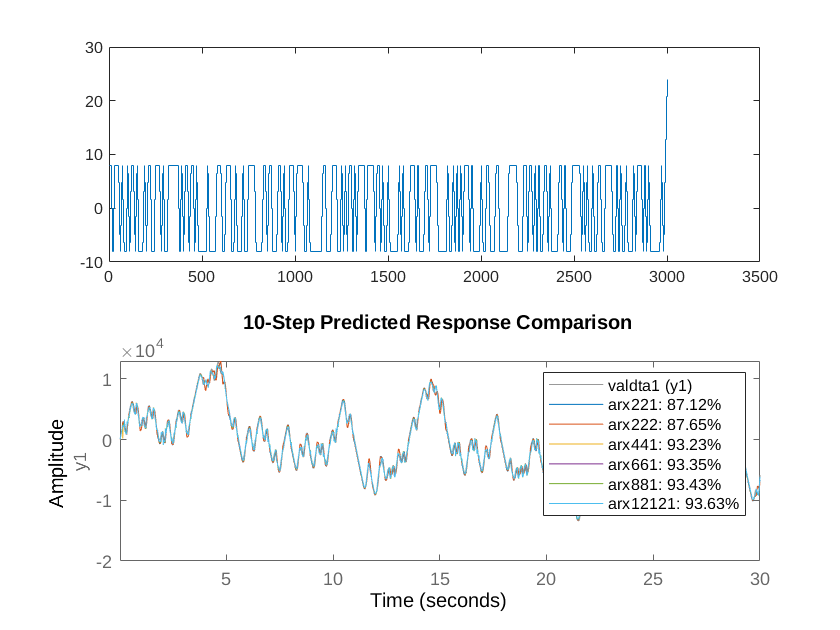

compare(valdta1, arx221, arx222, arx441, arx661, arx881, arx12121,10)

aic(arx221, arx222, arx441, arx661, arx881, arx12121)

Model quality according to the "nAIC" measure:
    6.1586    6.0558    3.0272    2.9608    2.9619    2.9307



## Export models for use in Simulink

[num, den] = tfdata(tf(arx661))

num = 1×1 cell array
    {[0 2.1185 3.9186 -12.8345 9.3031 -2.4980 0.8610]}


den = 1×1 cell array
    {[1 -3.3793 4.4484 -2.9526 1.1830 -0.3692 0.0698]}
